clc;
clear;

%MODELANDO CONTROLADOR
Kp = 9.07;
Ki = 11.7;
Ci = tf(Ki, [1 0]); %controlador Ki 
C = Ci + Kp; %Controlador PI

n = 1;
d = [1 6 5];
G1 = tf(n, d);
G2 = series(G1, C);
G = feedback(G2, 1) % Sistema com PI

G =
 
         9.07 s + 11.7
  ----------------------------
  s^3 + 6 s^2 + 14.07 s + 11.7
 
Continuous-time transfer function.
Model Properties


H = feedback(G1, 1) %Sistema sem PI

H =
 
        1
  -------------
  s^2 + 6 s + 6
 
Continuous-time transfer function.
Model Properties


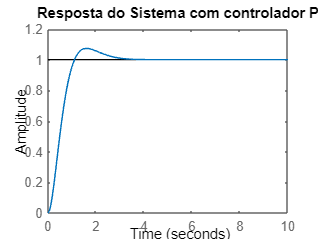


step(G, 10);
title("Resposta do Sistema com controlador PI")

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.7335
    TransientTime: 2.6601
     SettlingTime: 2.6601
      SettlingMin: 0.9139
      SettlingMax: 1.0734
        Overshoot: 7.3355
       Undershoot: 0
             Peak: 1.0734
         PeakTime: 1.6192


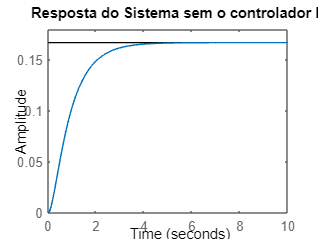

step(H, 10);
title("Resposta do Sistema sem o controlador PI")

stepinfo(H)

ans = struct with fields:
         RiseTime: 1.8358
    TransientTime: 3.3313
     SettlingTime: 3.3313
      SettlingMin: 0.1500
      SettlingMax: 0.1667
        Overshoot: 0
       Undershoot: 0
             Peak: 0.1667
         PeakTime: 10.6856


%rlocus(H)
sisotool(H)
